# Categorical index tables

Example script for Spectr-O-matic toolbox.

Script location: `Examples/catindex`

## Overview

This script performs the following types of operations:

- Subtract reference spectra for different groups of data (using **splitbinop**)

- Create a categorical index with **catindex**

- Perform calculations on groups of data (using **splitop**)

- Plot data per group

- Calculate parameters and create a pivot table

Data description:

- Spectra from two experiments are stored as text files in folders *Exp1*, *Exp2*

- Text file names contain information about the sample: mutant (wt, cm9 or cm13)  and treatment (nothing, 0.07% bdm, 0.1% bdm)

- Every text file contains three spectra - CD, HT, Abs.

Brief algorithm:

- Load data

- Subtract reference (baseline) spectra across experiments

- Perform simple bulk calculations 

- Create categorical index (catindex)

- Perform calculations on groups of data using the categorical index

- Plot spectra per group using the categorical index

- Calculate a parameter and create a pivot table

clear; close all

Loading spectra...
File 1: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD blank.txt
File 2: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm9 .txt
File 3: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm9+bdm 0.1%.txt
File 4: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm9+bdm 0.07%.txt
File 5: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm13 .txt
File 6: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm13+bdm 0.1%.txt
File 7: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD cm13+bdm 0.07%.txt
File 8: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD wt .txt
File 9: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD wt+bdm 0.1%.txt
File 10: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp1\CD wt+bdm 0.07%.txt


## 1) Load data

- Load text files: 10 files from Exp1 and 13 files from Exp2.

- Combine data into a single 23x3 data array `dat`

- Split data into two variables: `CD` (1st column of `dat`) and `Abs` (3rd column)

% Load text files from Exp1
exp1 = specdata.load('Exp1\*.txt', 'FileType', 'JWS'); 

Loading spectra...
File 1: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD blank.txt
File 2: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm9+bdm 0.1%.txt
File 3: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm9+bdm 0.01%.txt
File 4: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm9+bdm 0.07%.txt
File 5: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm9.txt
File 6: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm13+bdm 0.1%.txt
File 7: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm13+bdm 0.01%.txt
File 8: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm13+bdm 0.07%.txt
File 9: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD cm13.txt
File 10: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex\Exp2\CD wt+bdm 0.1%.txt
File 11: D:\Petar\OneDrive\Lab\MATLAB\Spectromatic\Examples\catindex

% Load text files from Exp1
exp2 = specdata.load('Exp2\*.txt', 'FileType', 'JWS');
% Create combined dataset
dat = [exp1; exp2];

% Split CD and absorption spectra
CD = dat(:,1); Abs = dat(:,3);

## 2) Subtract baseline across experiments

- Create an index of reference spectra (containing the keyword *blank*)

- Create a categorical index table `T` with a single variable *ExpID*

- Subtract reference spectra from the rest of the spectra, using ExpID as a grouping variable

bl  = CD.findindex('blank');  % find reference spectra
T   = CD.pt('ExpID');          % create a table T with one column containing ExpID
CD  = CD.splitbinop(@minus, ~bl, bl, T, 'ExpID')'; 
Abs = Abs.splitbinop(@minus, ~bl, bl, T, 'ExpID')';

## 3) Simple calculations on spectra

% Shift all Abs spectra to 0 at 750 nm
Abs = Abs - Abs.Yx(750);

% Normalize all CD spectra to the Abs maximum in the range 600-700 nm
CD = CD / Abs.max([600 700]);

% Truncate wavelength range
CD = CD.setxlim([620 720]);


## 4) Create categorical index

- Define the experiment: 2 variables (*mutant *and *bdm*) and list of possible values in struct `vardef`

- Create an index by categorizing the data based on a match of the file ID and the values of `vardef`

% Define variables
vardef.mutant = {'wt', 'cm9', 'cm13'};
vardef.bdm = {'?0%', '0.07%', '0.1%'}; % default value is 0% (marked with ?)

% Optionally define fancy variable labels to display. They can be numbers too.
vardisp.mutant = {'WT', 'CM9', 'CM13'};

% Create index by searching for vardef values in spectra ID's
C = CD.catindex(vardef, vardisp);

## 5) Calculations per group

Average spectra for the same mutant and bdm treatment using the categorical index.

% Average spectra using mutant and bdm as grouping variables
Avg = CD.splitop(@mean, C);

% Create a new index table for the averaged data
C = Avg.catindex(vardef, vardisp); 


Sort averaged data by mutant, bdm. Note that categorical variables are sorted in the order they are defined in `vardef`

[C, ri] = sortrows(C, {'mutant', 'bdm'});
Avg = Avg(ri);


## 6) Plot Spectra per group

- Plot the spectra in different figures separated by mutant.

- Write the mutant name in the figure title and bdm treatment in the legend.

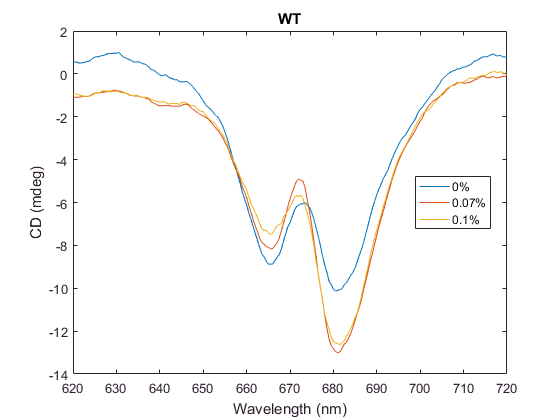

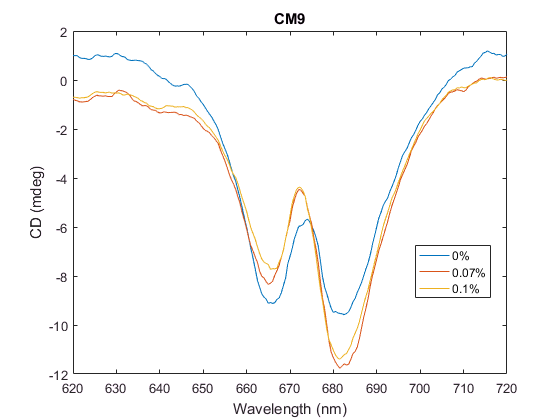

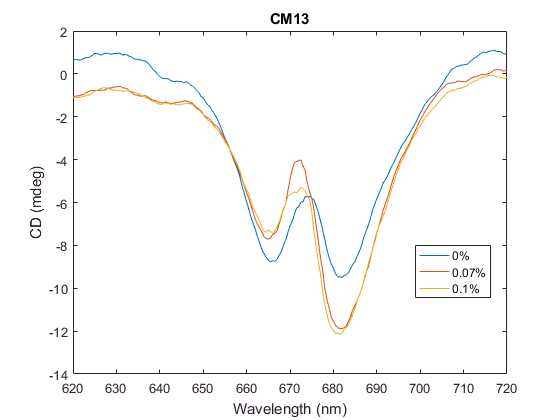

bdm = cellstr(C.bdm); % dm concentration for each spectrum;
Avg.set('ID', bdm).splitop(@plotf, C, {'mutant'}, [], 'PassGroupVars');

## 7) Create a parameter table 

- Calculate a parameter from the spectra and add it to the index table

- Make a parameter table separating mutants into columns

- Plot the table data

% Add calculated PeakRatio parameter
C.PeakRatio = Avg.Yx(665) ./ Avg.Yx(681);

% Make a wide table of PeakRatio with mutant in columns
PR = unstack(C,'PeakRatio','mutant');
disp(PR)

                        bdm       WT         CM9       CM13  
                       _____    _______    _______    _______

    CD wt              0%       0.87941    0.95828    0.91782
    CD wt+bdm 0.07%    0.07%    0.62081    0.71571     0.6519
    CD wt+bdm 0.1%     0.1%     0.58902    0.66368    0.60341

